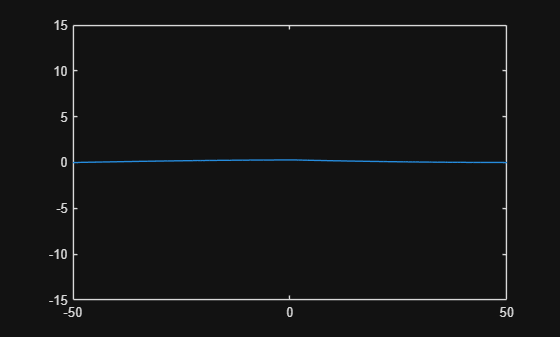

%{play around with z function (alter z trajectory), timespan (make very long), etc. --> try very rough oscillation%}
dtUfield = zeros(100, 2000);
dxUfield = zeros(100, 2000);
%Add back in initial data for particle to see what's what
%{try with dxUfield, compute a reimann sum, compute + plot field energy --> hopefully will oscillate getting smaller%}
for k = 1:100 %{we want intervals of 0.5 ideally, but that messes up tau%}, try 1:300

    tau = 0.5*k;

    alpha = 0.1;

    omega = 1;

    tcross = 1; %{come up with implicit definition, time where backwards light cone intersects particle world line; integral is 
    %{0 to tcross, think of it like 0 to t --> if particle is not in backwards light cone, = 0, otherwise do the other thing if the
    %{particle is  in the backwards light cone; check notes for this%}

    %{%}

    z = @(t) tanh(0.2*t); %3*sin(0.2*t); play with frequency to be in phase with wave it sources

    %{besselsource = @(tt,s,z) alpha .* besselj(0, omega .* sqrt(tt.^2 - (s - z).^2));%}
    %{bessel(t, tt, s, z(tt))%}

    Usource = @(t, s) compute_Usource(t, s, z, alpha, omega);%{same as bessel if particle in light cone, %}

    slin = linspace(-50, 50, 2000);
    dx = slin(2) - slin(1);

    for i = 1:length(slin)
        solved_Usource(i) = Usource(tau, slin(i));
        Ufield(k, i) = solved_Usource(i);
    end
    
    if k == 1
        dtUfield(k, :) = 0;
    else
        dtUfield(k, :) = (Ufield(k, :) - Ufield(k - 1, :)) / 1;
    end

    for s=1:2000
        if s == 1
            dxUfield(k, s) = 0;
        else
            dxUfield(k, s) = (Ufield(k, s) - Ufield(k, s - 1)) / dx;
        end
    end

    plot(slin, solved_Usource)
    axis([-50 50 -15 15])
    saveas(gcf, ['Frame' num2str(k) '.png'])

end


E = zeros(100,1);

for k = 1:100
    for s = 1:2000 
        E(k) = E(k) + dx * (dtUfield(k,s))^2 + dx * (omega^2)*(Ufield(k,s))^2 + dx * (dxUfield(k,s))^2;
    end
end

time = linspace(0,50,100)

time =          0    0.5051    1.0101    1.5152    2.0202    2.5253    3.0303    3.5354    4.0404    4.5455    5.0505    5.5556    6.0606    6.5657    7.0707    7.5758    8.0808    8.5859    9.0909    9.5960   10.1010   10.6061   11.1111   11.6162   12.1212   12.6263   13.1313   13.6364   14.1414   14.6465   15.1515   15.6566   16.1616   16.6667   17.1717   17.6768   18.1818   18.6869   19.1919   19.6970   20.2020   20.7071   21.2121   21.7172   22.2222   22.7273   23.2323   23.7374   24.2424   24.7475


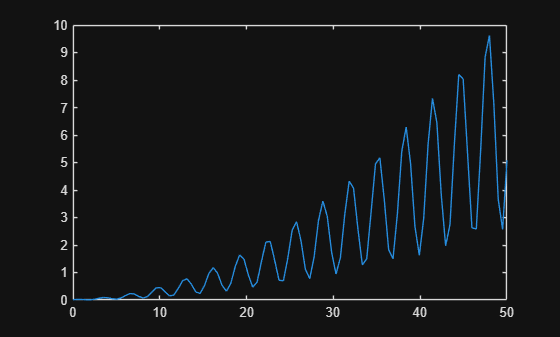

plot(time,E)


% also try plotting change in E vs t

function U = compute_Usource(t, s, z, alpha, omega)
    
    if t^2 >= (s - z(t))^2
        U = integral(@(tt) besselCompute(t, tt, s, z(tt), alpha, omega), 0, t);
        %{introduce uInt --> integrand computed at many times between 0 and t
        %{introduce tlin, chop up integral, make uInt a vector where each component is
        %{integrand evaluated at each time of tlin (trapz function)%}
        %{alternate method for B array ^%}
    else
        U = 0;
    end
end

function B = besselCompute(t, tt, s, ztt, alpha, omega)
    n = length(tt);
    B = [];
    for i = 1:n
        if abs(t - tt(i)) > abs(s - ztt(i))
            B(i) = alpha .* besselj(0, omega .* sqrt(t.^2 - (s - ztt(i).^2)));
        else 
            B(i) = 0;
        end
    end
end

